%% Combining the Data from the sources

clc
fileList = dir('*.csv')

fileList = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


clear MasterInput

MasterInput = removevars(readtable(fileList(1).name,MissingRule="omitrow",ReadRowNames=false),"Var1");
if length(fileList) >1
for i=2:length(fileList)
    MasterInput = [MasterInput ; removevars(readtable(fileList(i).name,MissingRule="omitrow",ReadRowNames=false),"Var1")];
end
end



%% Removing separation onf input and output
inputData = removevars(MasterInput, {'traffic','roadSurface','drivingStyle'});
TestCategory=MasterInput.traffic;

%% Spliting training and test data
rng('default') %Mersenne Twister generator with seed 
%rng('shuffle') %Mersenne Twister generator with current time 
Partition = cvpartition (TestCategory, 'Holdout', 0.10);


trainData = training (Partition);
inputDataTrain = inputData(trainData,:);
OutputDataTrain = TestCategory(trainData);

testData = test(Partition);
inputDatatest = inputData(testData,:); 
OutputDatatest=TestCategory(testData);


%% Classification training
tic
ClassifiserObject = fitctree(inputDataTrain, OutputDataTrain) 

ClassifiserObject =   ClassificationTree
           PredictorNames: {1×14 cell}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'HighCongestionCondition'  'LowCongestionCondition'  'NormalCongestionCondition'}
           ScoreTransform: 'none'
          NumObservations: 21386


  Properties, Methods


%Enable CrossVal on for visualisation - Does not perform "predict"
%ClassifiserObject = fitctree(inputDataTrain, OutputDataTrain,'CrossVal','on') 
toc

Elapsed time is 0.187277 seconds.




%%Visualisation for the fitctree -Working - Enable if needed
%numBranches = @(x)sum(x.IsBranch);
%mdlDefaultNumSplits = cellfun(numBranches, ClassifiserObject.Trained);
%view(ClassifiserObject.Trained{1},'Mode','graph')



%SVM classification - working Enable if needed

%%SVM classifier for binary classification
%SVMClassifiserObject = fitcsvm(inputDataTrain,OutputDataTrain) 

%SVM classifier for Multiclass classification
[a,~]=grp2idx(OutputDataTrain);
train_ip = gpuArray(table2array(inputDataTrain));
train_op = gpuArray(a);
SVMClassifiserObject = fitcecoc (train_ip,train_op);



%Prediction / Testing 
TestPreModel = predict(ClassifiserObject, inputDatatest);
%TestPreModelSVM = predict(SVMClassifiserObject, inputDatatest);

%Calculation accuracy
index = cellfun(@strcmp, OutputDatatest, TestPreModel)

index = 2376×1 logical array
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1


score = sum(index)/length(OutputDatatest)

score = 0.9731

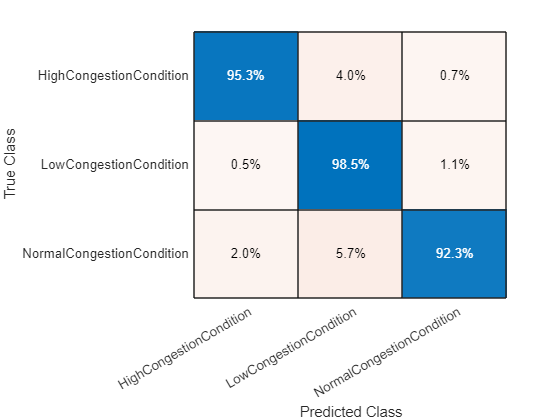


%Calculation accuracy 
%indexSVM = cellfun(@strcmp, OutputDatatest, TestPreModelSVM)
%scoreSVM = sum(indexSVM)/length(OutputDatatest)

figure;
confusionchart(OutputDatatest,TestPreModel,"Normalization","row-normalized")


%   figure;
%confusionchart(OutputDatatest,TestPreModelSVM,"Normalization","row-normalized")

Unrecognized function or variable 'TestPreModelSVM'.